# Introduction

This live script contains examples of reachable workspaces for 2D robots. For each example this includes: 

- DH Parameters

- Theoretical Workspace

- Generated Workspace

syms theta1 theta2 theta3 real
syms d1 d2 real

# Example 1

This is a 2 DOF planar robot with rotational joints (unconstrained), where the appropriate reachable workspace that can be determined by the extreme positions is highlighted. 

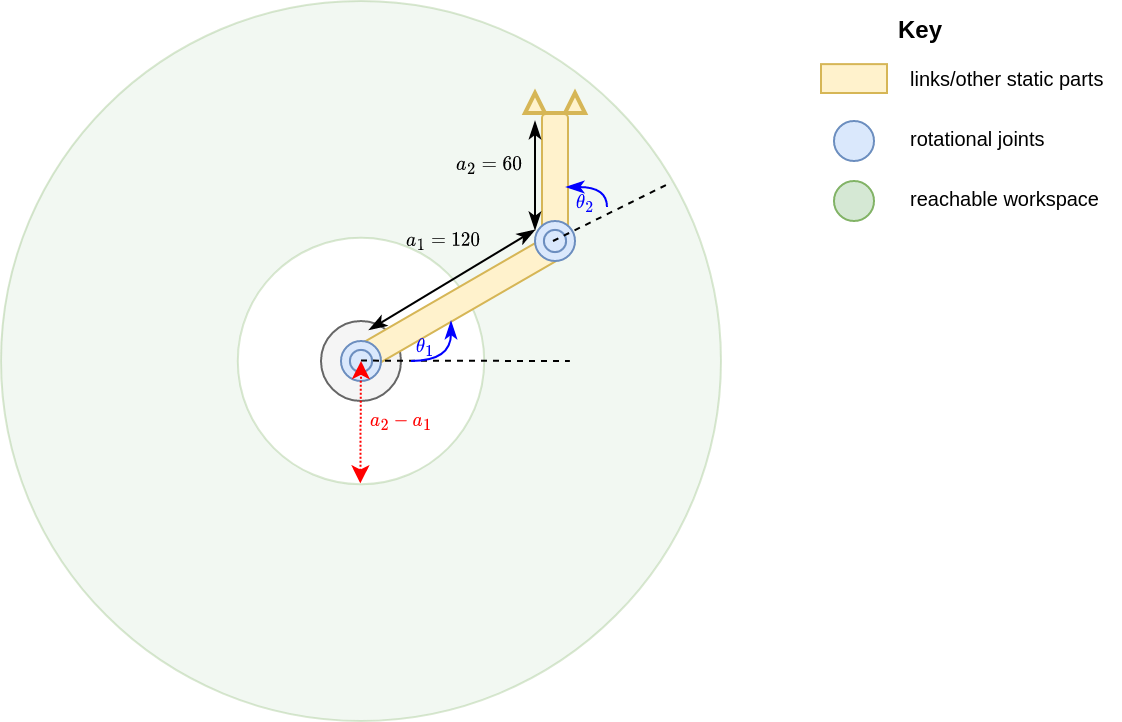

Below is the according code with DH parameters to approximate this space.

% DH parameters
test_dh = [0 0 0 theta1; ...
           120 0 0 theta2; ...
           60 0 0 0]
% Parameter ranges
theta1_range = linspace(0,2*pi, 180);
theta2_range = linspace(0,2*pi, 180);
test_map = containers.Map({'theta1', 'theta2'},{theta1_range,theta2_range})

% Workspace plotting function + timing
plot2dworkspace(test_dh, test_map)

$$test\_dh = \left(\begin{array}{cccc} 0 & 0 & 0 & \theta_{1}\\ 120 & 0 & 0 & \theta_{2}\\ 60 & 0 & 0 & 0 \end{array}\right)$$

# Example 2

This is an example of a 3 DOF robot (2 prismatic, 1 rotational). Note here that the two prismatic joints each have a maximum extension of 1, which ranges the DH parameters $d_1 ,d_2 \in \left\lbrack 2,3\right\rbrack$ when we factor in the lengths of the links they extend from. The rotational joint $\theta_{3\;}$is unconstrained. The reachable workspace is less intuitive in this case, but can be determined by drawing out the extreme positions of each joint.

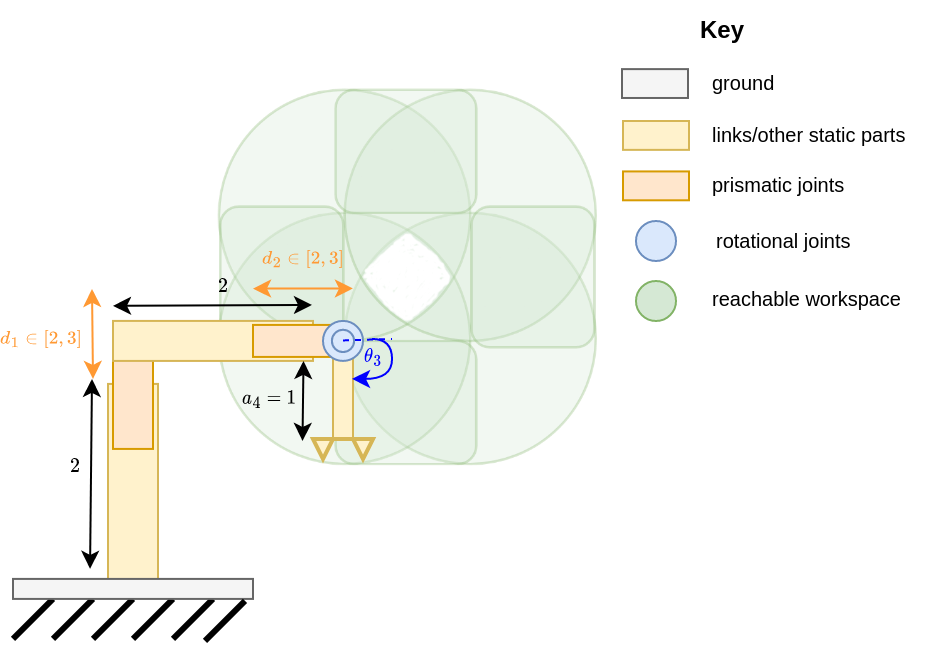

Below is the code showing how to plot this example. 

% DH parameters
test_dh = [0 0 d1 0; ...
           0 -pi/2 d2 pi/2; ...
           0 -pi/2 0 theta3; ...

test_map =   Map with properties:

        Count: 2
      KeyType: char
    ValueType: any


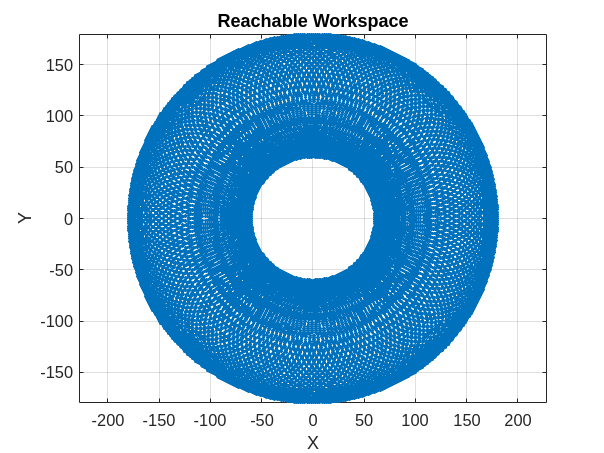

           1 0 0 0]

% Parameter ranges

d1_range = linspace(2,3, 50);
d2_range = linspace(2,3, 50);
theta3_range = linspace(0,2*pi, 180);
test_map = containers.Map({'d1', 'd2', 'theta3'},{d1_range,d2_range, theta3_range})

% Runs plot command with additional optional parameters, including verbose
% logging. Shows various details like transformation matrix used, number of
% positions calculated, etc.
tic
plot2dworkspace(test_dh, test_map, 0.001, true)
toc

$$test\_dh = \left(\begin{array}{cccc} 0 & 0 & d_{1} & 0\\ 0 & -\frac{\pi }{2} & d_{2} & \frac{\pi }{2}\\ 0 & -\frac{\pi }{2} & 0 & \theta_{3}\\ 1 & 0 & 0 & 0 \end{array}\right)$$

% A somewhat convoluted PDF export procedure to save a PDF of the .mlx file
% for github. You can ignore this.
file_name = 'plot2dworkspace_examples';
current_mlx = which(file_name);
[path_to_file, name, ext] = fileparts(current_mlx);
mlx_path = fullfile(path_to_file, (file_name + ".mlx"));

test_map =   Map with properties:

        Count: 3
      KeyType: char
    ValueType: any


final transformation matrix from base to end-effector:


$$\left(\begin{array}{cccc} 0 & 0 & -1 & 0\\ -\sin\left(\theta_{3}\right) & -\cos\left(\theta_{3}\right) & 0 & d_{2}-\sin\left(\theta_{3}\right)\\ -\cos\left(\theta_{3}\right) & \sin\left(\theta_{3}\right) & 0 & d_{1}-\cos\left(\theta_{3}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

expressions for position:
x = 0
y = d2 - sin(theta3)
z = d1 - cos(theta3)
allocating 450000 possible DH parameter combinations...
calculating positions from expressions...


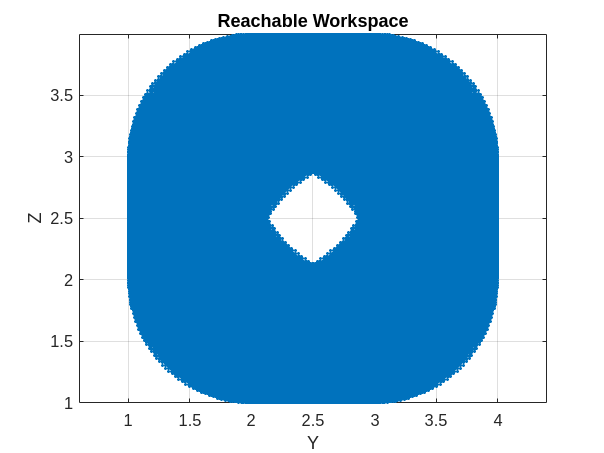

Elapsed time is 0.188144 seconds.


pdf_path = fullfile(path_to_file, (file_name + ".pdf"));
export(mlx_path, pdf_path);